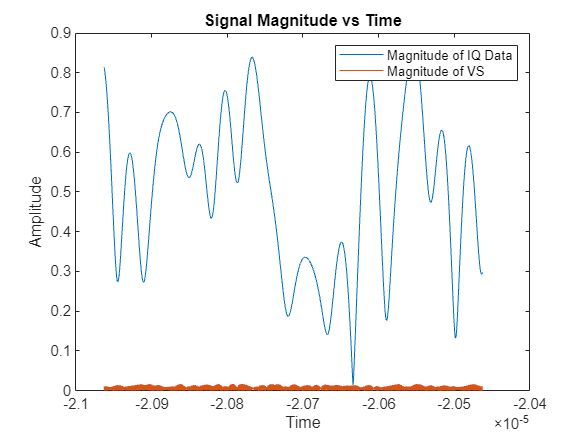

clear all
close all

%% read data captured by digitizing oscilloscope after downconverting to 1.5GHz carrier 
load('data91vars');

load('AWG_Signal_3GHz.mat')

plot(time(1:5000),abs(iqdata(1:5000)),time(1:5000),abs(vs(1:5000)))
legend('Magnitude of IQ Data', 'Magnitude of VS')
xlabel('Time')
ylabel('Amplitude')
title('Signal Magnitude vs Time')


fs_in = fs

fs_in = 3.2000e+10

dt = time(2) - time(1);   % time step between samples
Fs = 1 / dt; %changing this actually has an impact on the output spectrum

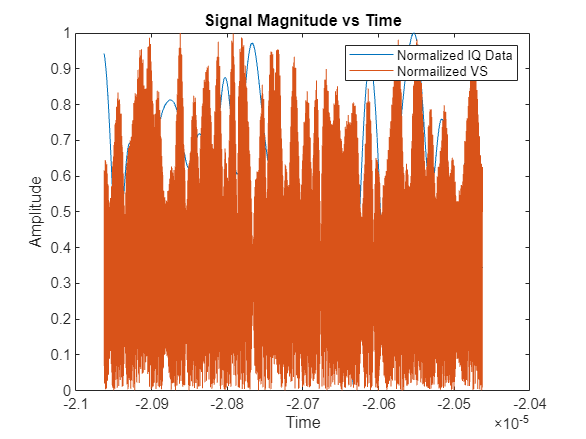

% Original signals (magnitude)
iq_mag = abs(iqdata(1:5000));
vs_mag = abs(vs(1:5000));
t = time(1:5000);

% Normalize to max magnitude
iq_norm = iq_mag / max(iq_mag);
vs_norm = vs_mag / max(vs_mag);

plot(time(1:5000),abs(iq_norm(1:5000)),time(1:5000),abs(vs_norm(1:5000)))
legend('Normalized IQ Data', 'Normailized VS')
xlabel('Time')
ylabel('Amplitude')
title('Signal Magnitude vs Time')


vfft=fft(vs);

plot(time(1:5000),abs(iq_norm(1:5000)),time(1:5000),abs(vs_norm(1:5000)))
legend('Normalized IQ Data', 'Normailized VS')
xlabel('Time')
ylabel('Amplitude')
title('Signal Magnitude vs Time')

Fc=1.5e9;

SymbolRate=1e8;
vssmall=vs(1:1000000);
% Digital downconversion to Baseband
vhsmall=hilbert(vssmall-mean(vssmall));
vbb=vhsmall.*(exp(2*pi*1i*Fc/Fs*(1:length(vhsmall))))';
% vbb=hilbert(vssmall-mean(vssmall)).*exp(-2*pi*1i*Fc/Fs*(1:length(vssmall)));
% vbb = vbb/max(abs(vbb));

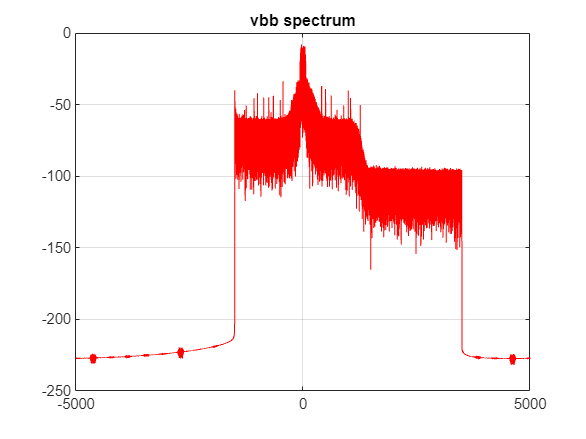

%%% look at power spectrum
vbbfft=fft(vbb);     
% %spectrum_analysis(vbb,Fs,'generic','blackman',1000e3,4,'g');
XX = fftshift(vbbfft);
Pxx = 10*log10(XX.* conj(XX) / (length(XX)));
f = Fs*((0:length(Pxx)-1)/length(Pxx) - 0.5)/1e6;
figure(2)
plot(f,Pxx,'r'); grid on
title('vbb spectrum')

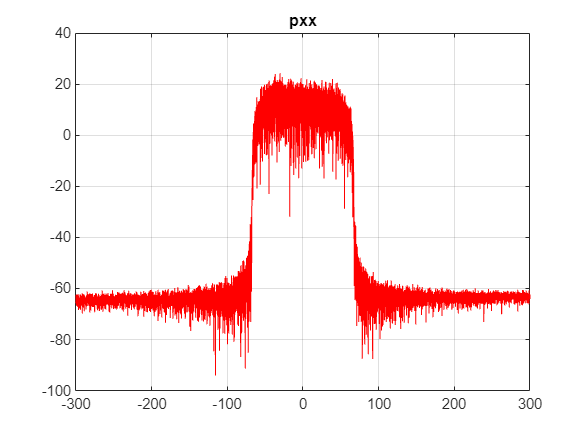

vbb=vbb/max(abs(vbb));

%% input data generated by matlab iqtools on a 3GHz carrier sent to AWG
Fciq=3e9;
iqdatares=resample(iqdata,5,16);
iqbb=iqdatares.*(exp(2*pi*1i*Fciq/Fs*(1:length(iqdatares))))';

%%% look at power spectrum
iqfft=fft(iqbb);  
% %spectrum_analysis(vbb,Fs,'generic','blackman',1000e3,4,'g');
XX = fftshift(iqfft);
Pxx = 10*log10(XX.* conj(XX) / (length(XX)));
f = Fs*((0:length(Pxx)-1)/length(Pxx) - 0.5)/1e6;
figure(3)
plot(f,Pxx,'r');
title("pxx")
xlim([-300 300])
grid on

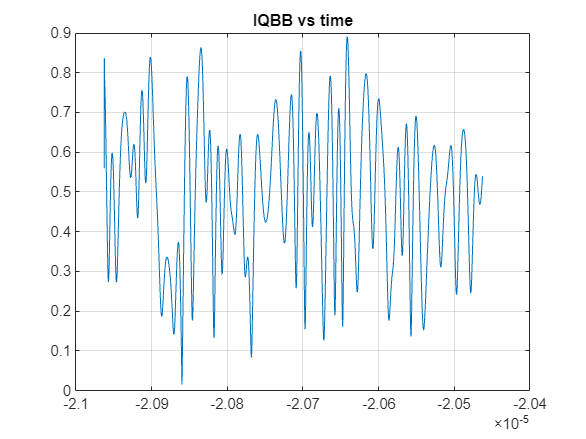

figure(4)
plot(time(1:5000),abs(iqbb(1:5000)))
title("IQBB vs time")
grid on

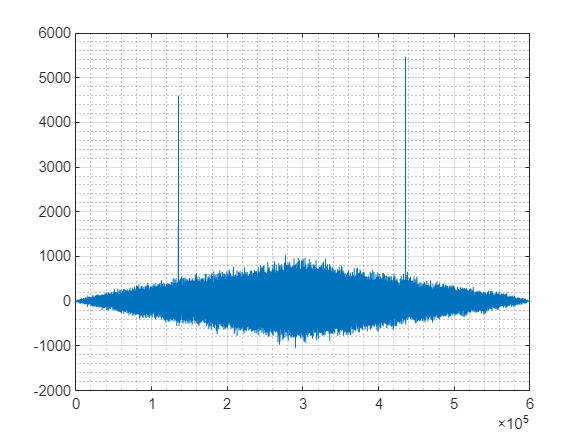


%%% time alignment
x=abs(iqbb);
y=abs(vbb(1:length(x)));
xcc=xcov(y,x);
figure(66666)
plot(xcc)
grid on
grid minor

Lag=findshiftAM(x,y);   %%% finds best fit index for shift

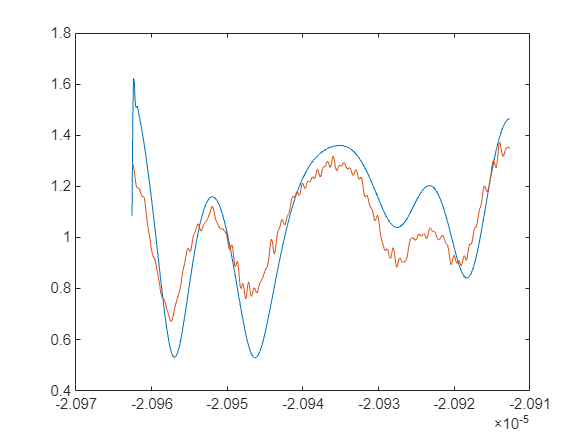

%% requires circular data?
Lagint=floor(Lag);
vbbshift=vbb(1-Lagint:length(x)-Lagint);
iqbbnorm=iqbb/max(iqbb);
iqbbmag=abs(iqbbnorm);
vbbnorm=vbbshift/max(vbbshift);
vbbmag=abs(vbbnorm);
% vbbnorm1=vbbshift/max(vbbshift);

% RMS power normalization instead of peak normalization
iq_rms = rms(iqbb);          
vbb_rms = rms(vbbshift);     

iqbb_rms_norm = iqbb / iq_rms;
vbb_rms_norm  = vbbshift / vbb_rms;

% Envelope magnitude
iqbbmag_rms = abs(iqbb_rms_norm);
vbbmag_rms  = abs(vbb_rms_norm);


plot(time(1:500),abs(iqbb_rms_norm(1:500)),time(1:500),abs(vbb_rms_norm(1:500)))

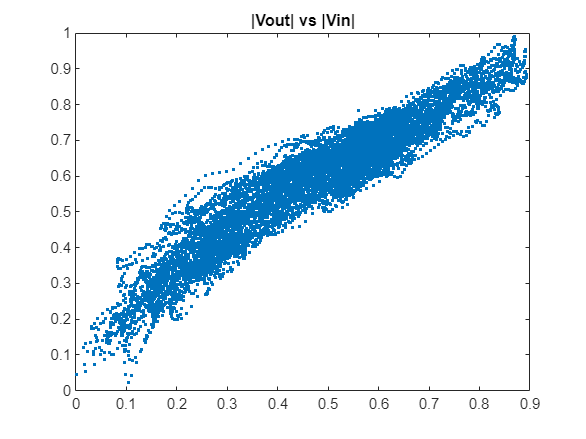


plot(iqbbmag(1:10000),vbbmag(1:10000),'.')
title("|Vout| vs |Vin|")

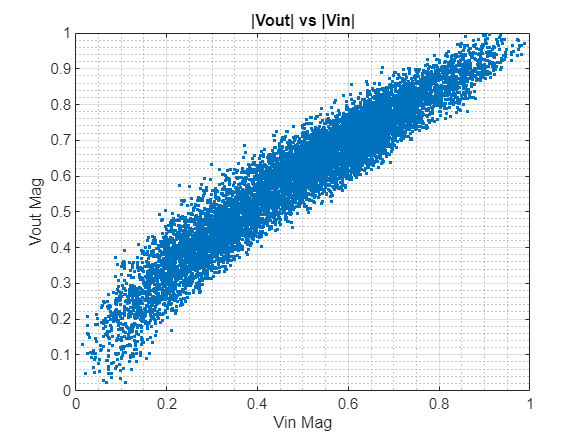


lpFilt1 = designfilt('lowpassfir', 'PassbandFrequency', 1e9,...
             'StopbandFrequency', 1.5e9, 'PassbandRipple', 0.5, ...
             'StopbandAttenuation', 65, 'SampleRate', 1e10);
iqfilt=filtfilt(lpFilt1,iqbbnorm);
iqdd=downsample(iqfilt,5);
vfilt=filtfilt(lpFilt1,vbbnorm);
vdd=downsample(vfilt,5);
vdd=-vdd;

iq_1G=downsample(iqbb,10);
v_1G=downsample(vbbshift,10);

% vddr=resample(vdd,20,21);
% vdd=vddr;
% iqdd=iqdd(1:length(vddr));
iqddmag=abs(iqdd);
vddmag=abs(vdd);
figure(111)
plot(iqddmag(1:10000),vddmag(1:10000),'.')
title("|Vout| vs |Vin|")
% Labels and Title
xlabel('Vin Mag');
ylabel('Vout Mag');
xlim([0 1])
ylim([0 1])

grid on
grid minor

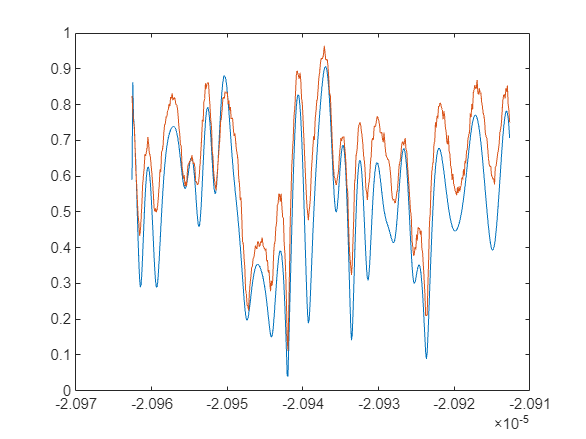

figure(99)
plot(time(1:500),iqddmag(1:500),time(1:500),vddmag(1:500))

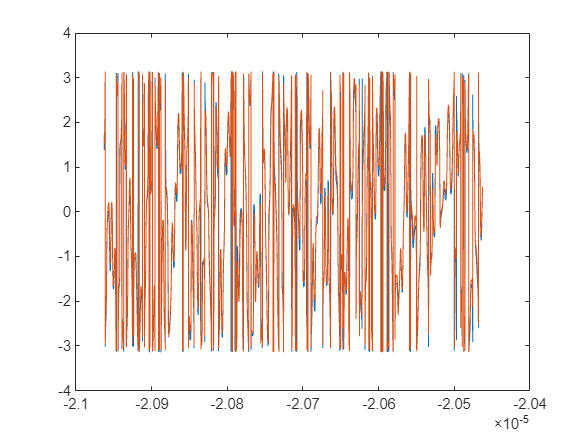


figure(999)
iqddph=angle(iqdd);
vddph=angle(vdd);
plot(time(1:5000),iqddph(1:5000),time(1:5000),vddph(1:5000))

errmagorig=abs(vdd-iqdd);
errnormorig=sqrt(sum(errmagorig.^2)/length(vdd))

errnormorig = 0.1471

vddrms=sqrt(sum(abs(vdd).^2)/length(vdd))

vddrms = 0.6362

errrmsorig=errnormorig/vddrms

errrmsorig = 0.2313

f_plot = Fs*((0:length(iqdd)-1)/length(iqdd) - 0.5)/1e6;

figure(135)
[P_spec_input, F_spec_input] = spec_plot(iqbb,1/Fs,135,'Input spectrum');

acpr value: -85.25 dB


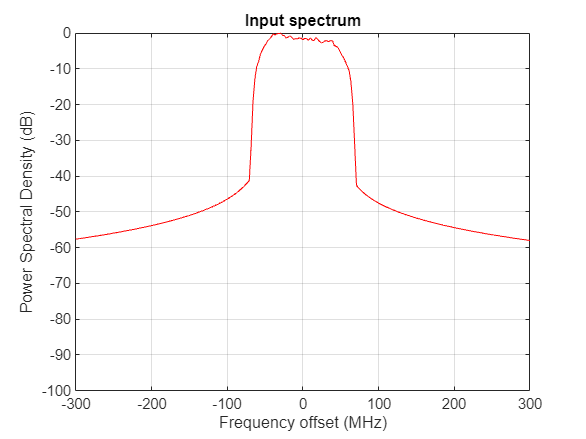

axis([-300 300 -100 0])

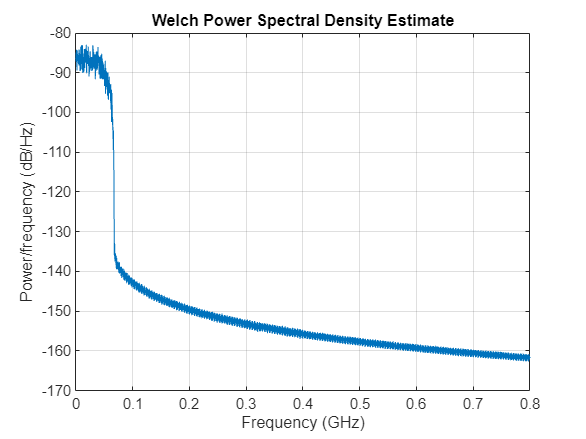

figure(1351)
pwelch(iqbb,[],[],[],Fs)      %%% spectrum of output
xlim([0 0.8])


figure(136)
[P_spec_out, F_spec_out] = spec_plot(vbbshift,1/Fs,135,'Output spectrum');

acpr value: -25.15 dB


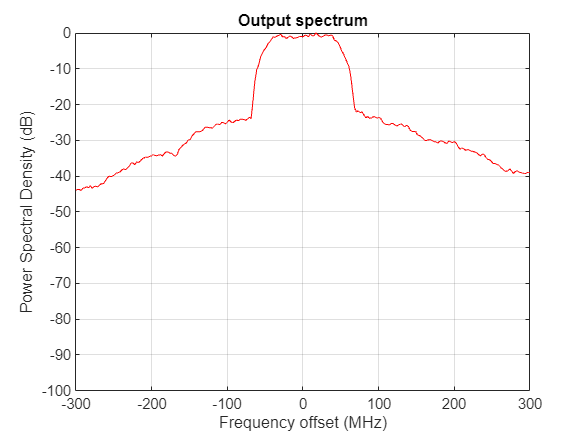

axis([-300 300 -100 0])

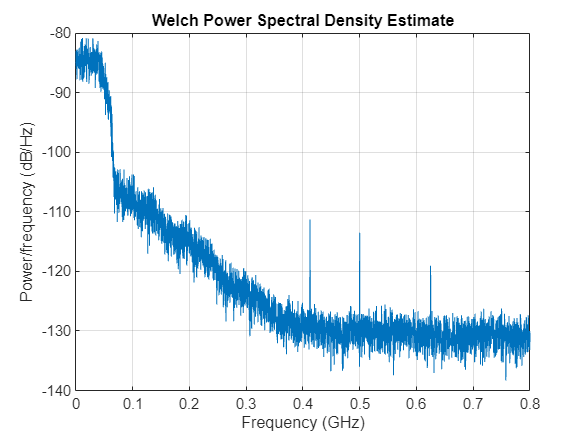

figure(1351)
pwelch(vbbshift,[],[],[],Fs)      %%% spectrum of output
xlim([0 0.8])

npoints=length(iqbb);  % Number of points

% Time vector
t = (0:npoints-1)/Fs;

power_avg_input = trapz(t, abs(iqbb).^2) / ((t(end) - t(1))*100);  % Using numerical integration

power_input = 10 * log10(power_avg_input/1e-3);
fprintf('Matlab input data Average Power (dBm): %f dBm\n', power_input);

Matlab input data Average Power (dBm): 4.253201 dBm



power_avg_output = trapz(t, abs(vbbshift).^2) / ((t(end) - t(1))*100);  % Using numerical integration

power_output = 10 * log10(power_avg_output/1e-3);
fprintf('Matlab output data Average Power (dBm): %f dBm\n', power_output);

Matlab output data Average Power (dBm): 5.579950 dBm


%create splits

%TrainIn = iqdata(1:300000); % Extract the data
%TrainOut = vbb(1:300000); % Extract the data

TrainIn = iq_1G(1:30000); % Extract the data
TrainOut = v_1G(24004:30000); % Extract the data

npoints=length(TrainIn);
% Time vector
t = (0:npoints-1)/Fs;

disp(sprintf('Baseband Input Peak-to-average ratio: %1.2f dB', 20*log10(max(abs(TrainIn))/rms(abs(TrainIn)))));

Baseband Input Peak-to-average ratio: 5.72 dB



PoutpkW=max(abs(TrainIn))^2/2/50;     %% peak output power in W
PinpkdBm=10*log10(PoutpkW)+30     %%% peak output power in dBm

PinpkdBm = 9.9725


power_avg_input = trapz(t, abs(TrainIn).^2) / ((t(end) - t(1))*100);  % Using numerical integration

power_input = 10 * log10(power_avg_input/1e-3);
fprintf('Input data Average Power (dBm): %f dBm\n', power_input);

Input data Average Power (dBm): 4.253418 dBm



disp(sprintf('Baseband Output Peak-to-average ratio: %1.2f dB', 20*log10(max(abs(TrainOut))/rms(abs(TrainOut)))));

Baseband Output Peak-to-average ratio: 4.04 dB



PoutpkW=max(abs(TrainOut))^2/2/50;     %% peak output power in W
PoutpkdBm=10*log10(PoutpkW)+30     %%% peak output power in dBm

PoutpkdBm = 9.7437


%power_avg_input = trapz(t, abs(TrainOut).^2) / ((t(end) - t(1))*100);  % Using numerical integration

%power_input = 10 * log10(power_avg_input/1e-3);
%fprintf('Output data Average Power (dBm): %f dBm\n', power_input);

figure(137)
[P_spec_Traininput, F_spec_Traininput] = spec_plot(TrainIn,10/Fs,100,'Input train spectrum');

acpr value: -85.25 dB


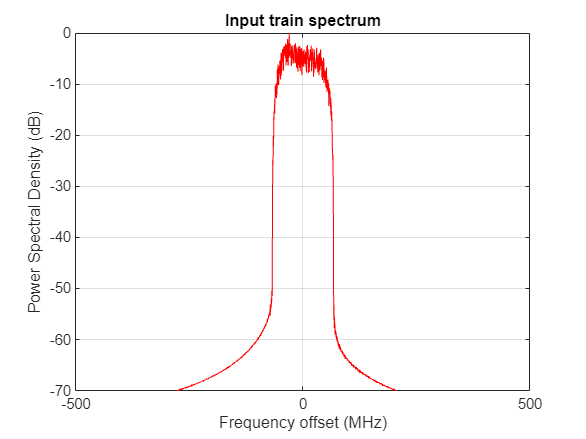

axis([-500 500 -70 0])

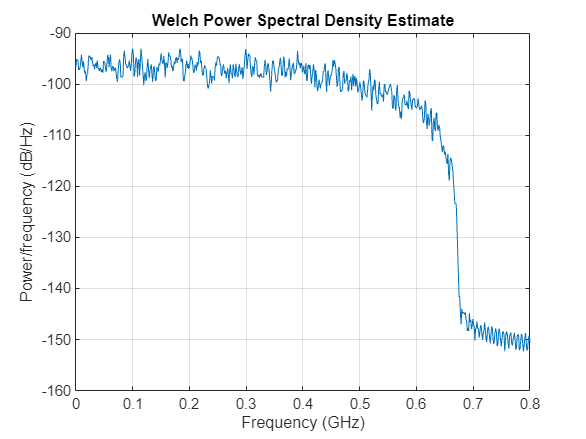

figure(1351)
pwelch(TrainIn,[],[],[],Fs)      %%% spectrum of output
xlim([0 0.8])

% 
% figure(139)
% [P_spec_iqdd, F_spec_iqdd] = spec_plot(iqbbnorm,1/Fc,135,'iqbbnorm spectrum');
% axis([-300 300 -100 0])
% figure(1351)
% pwelch(iqfilt,[],[],[],Fs)      %%% spectrum of output
% xlim([0 0.8])

figure(137)
[P_spec_Trainout, F_spec_Trainout] = spec_plot(TrainOut,10/Fs,135,'Output train spectrum');

acpr value: -25.21 dB


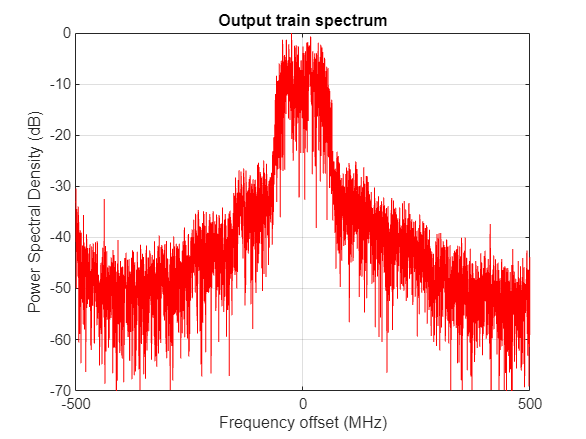

axis([-500 500 -70 0])

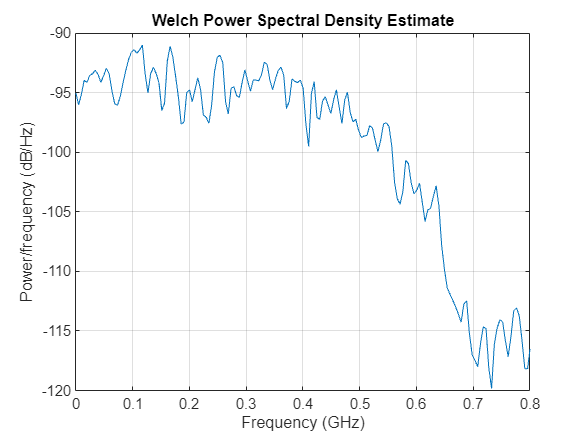

figure(1351)
pwelch(TrainOut,[],[],[],Fs)      %%% spectrum of output
xlim([0 0.8])

% Example: create column names automatically
numInCols = size(TrainIn, 2);
numOutCols = size(TrainOut, 2);

inNames = arrayfun(@(i) sprintf('TrainIn_%d', i), 1:numInCols, 'UniformOutput', false);
outNames = arrayfun(@(i) sprintf('TrainOut_%d', i), 1:numOutCols, 'UniformOutput', false);

% Combine into a table
%T1 = array2table([TrainIn, TrainOut], 'VariableNames', [inNames, outNames]);

% Write to CSV
%writetable(T1, 'post_dist_bb_1GHZ.csv');

% %%AM-AM plots
% 
% % === Parameters ===
% N   = 300000;          % Number of samples
% Fs  = 100e6;           % Sample rate (Hz)
% f0  = 1e6;             % Frequency (Hz)
% R   = 50;              % Load resistance (Ohms)
% dBm_levels = --10:1:30;  % Power levels (dBm)
% rng(1);                % Reproducible random phases
% 
% % === Create output folder ===
% out_folder = 'sinewaves';
% if ~exist(out_folder, 'dir')
%     mkdir(out_folder);
% end
% 
% % === Time vector ===
% t = (0:N-1).'/Fs;
% 
% % === Convert dBm → peak voltage ===
% P_w   = 10.^((dBm_levels - 30)/10);  % power in Watts
% Vrms  = sqrt(P_w * R);
% Vpk   = sqrt(2) * Vrms;
% 
% % === Generate and save sinusoids ===
% for k = 1:length(dBm_levels)
%     dBm = dBm_levels(k);
%     phi = 2*pi*rand;  % random phase
% 
%     % Complex analytic sinusoid
%     s_complex = Vpk(k) * exp(1j*(2*pi*f0*t + phi));
% 
%     % Split into real and imaginary parts
%     data = [real(s_complex), imag(s_complex)];
% 
%     % Define file name (e.g., sin_doherty_-5.csv)
%     filename = sprintf('%s/sin_doherty_%+d.csv', out_folder, dBm);
% 
%     % Create table with headers
%     T = array2table(data, 'VariableNames', {'Real', 'Imag'});
% 
%     % Save to CSV
%     writetable(T, filename);
% 
%     fprintf('Saved: %s (%.1f dBm)\n', filename, dBm);
% end
% 
% fprintf('All sinusoids saved in folder: "%s"\n', out_folder);


## Results processing




%load file generated by python Post_distortion script
%load('RNN_V3_td.mat')
%load('DohertyTD3.mat')
load('LSTM_TD3_V1GHz.mat')




figure(137)
[P_spec_predicted, F_spec_predicted] = spec_plot(xI_predict,10/Fs,135,'Predicted Output');

acpr value: -32.92 dB


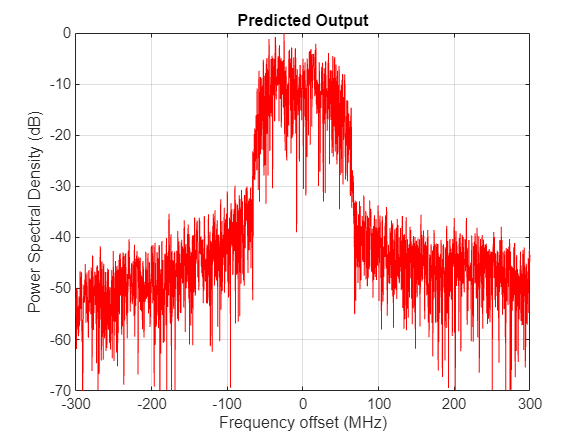

%[P_spec_predicted, F_spec_predicted] = spec_plot(xI_predict,1/Fs,135,'Predicted Output');
axis([-300 300 -70 0])

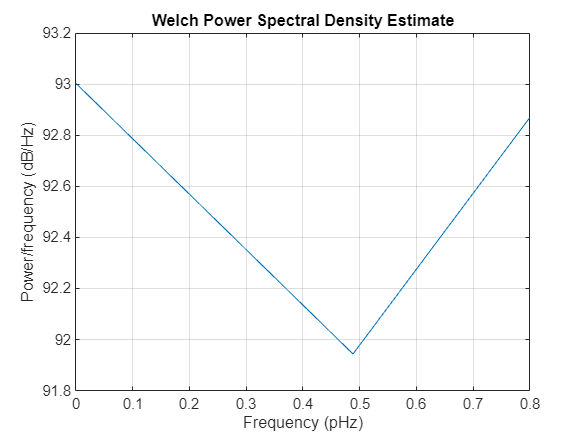

figure(1351)
pwelch(xI_predict,[],[],[],10/Fs)      %%% spectrum of output
xlim([0 0.8])


npoints=length(xI_predict);
% Time vector
t = (0:npoints-1)/Fs;



disp(sprintf('Baseband Predicted Peak-to-average ratio: %1.2f dB', 20*log10(max(abs(xI_predict))/rms(abs(xI_predict)))));

Baseband Predicted Peak-to-average ratio: 5.49 dB



PoutpkW=max(abs(xI_predict))^2/2/50;     %% peak output power in W
PredictedPoutpkdBm=10*log10(PoutpkW)+30     %%% peak output power in dBm

PredictedPoutpkdBm = 9.7767


power_avg_input = trapz(t, abs(xI_predict).^2) / ((t(end) - t(1))*100);  % Using numerical integration

power_input = 10 * log10(power_avg_input/1e-3);
fprintf('Predicted data Average Power (dBm): %f dBm\n', power_input);

Predicted data Average Power (dBm): 4.283060 dBm


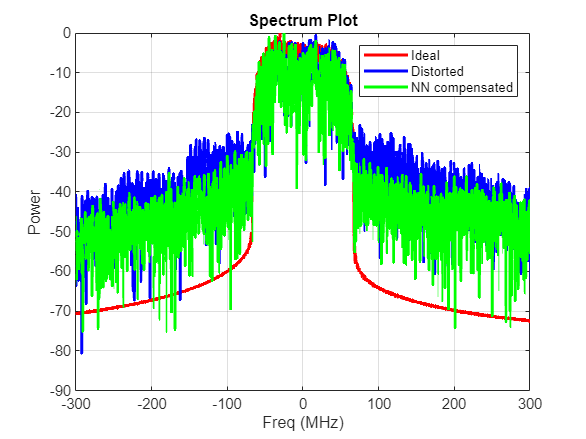

% Plot
figure;
plot(F_spec_Traininput, P_spec_Traininput, 'r-', 'LineWidth', 2); % First line in red
hold on;
plot(F_spec_Trainout, P_spec_Trainout, 'b-', 'LineWidth', 2); % Second line in blue dashed
plot(F_spec_predicted, P_spec_predicted, 'g-', 'LineWidth', 2); % Second line in blue dashed
hold off;

% Labels and Title
xlabel('Freq (MHz)');
ylabel('Power');
xlim([-300 300])
title('Spectrum Plot');
legend('Ideal', 'Distorted', 'NN compensated');
grid on;



% % Define time range
% t_start = 0;           % Start time in seconds
% t_end = 30e-6;         % End time in seconds (30 microseconds)
% 
% % Generate linearly spaced time vector
% time = linspace(t_start, t_end, 30000);
% 
% % Display basic info
% disp(['Time vector size: ', num2str(size(time))]);
% disp(['First time value: ', num2str(time(1)), ' s']);
% disp(['Last time value: ', num2str(time(end)), ' s']);
% 
% 
% 
% save('Sim10dbmVinVout.mat', 'time', 'xI_predict7dB', 'output_dist_7dB', 'output_predist_7dB', 'post_predict10dB', 'output_dist_10dB')

data = readtable('post_dist_bb_1GHZ_csv.csv');

% load('Mem_predist_predictions.mat')
% 
% Pre_mem_SP = xI_predict;

Post_mem_SP = xI_predict;





% Extract each variable
x_real = data.xI_real;
x_imag = data.xI_imag;
y_real = data.yout_real;
y_imag = data.yout_imag;

% Combine into complex numbers if needed
x_mem_complex = complex(x_real, x_imag);
y_mem_complex = complex(y_real, y_imag);

%Post_mem_SP = y_mem_complex(240001:300000);
% 
% % Read the CSV file into a table
% data2 = readtable('Doherty_env_sim_4_20_2025_input_output.csv');
% 
% % Extract each variable
% x_pd_real = data2.xI_real;
% x_pd_imag = data2.xI_imag;
% y_pd_real = data2.yout_real;
% y_pd_imag = data2.yout_imag;

% Combine into complex numbers if needed
% x_pd_complex = complex(x_pd_real, x_pd_imag);
% y_pd_complex = complex(y_pd_real, y_pd_imag);



% %normalize vectors to their peak value
% 
% t2 = (0:length(y_mem_complex)-1)/Fs;
% %sanityIn = sanityIn .* 10^(22.5/20); % Scale the values
% 
% power_avg_input = trapz(t2, abs(y_mem_complex).^2) / ((t2(end) - t2(1))*100);  % Using numerical integration
% 
% power_input = 10 * log10(power_avg_input/1e-3);
% fprintf('Sim output data Average Power (dBm): %f dBm\n', power_input);
% 
% x_mem_complex = x_mem_complex .* 10^(-6.7/20); % Scale the values
% 
% 
% power_avg_input = trapz(t2, abs(x_mem_complex).^2) / ((t2(end) - t2(1))*100);  % Using numerical integration
% 
% power_input = 10 * log10(power_avg_input/1e-3);
% fprintf('Sim Input data Average Power (dBm): %f dBm\n', power_input);
% 
% % Extract the real and imaginary parts
% xI_real = real(x_mem_complex);
% xI_imag = imag(x_mem_complex);
% yout_real = real(y_mem_complex);
% yout_imag = imag(y_mem_complex);
% 
% % Combine into one matrix
% data = [xI_real, xI_imag, yout_real, yout_imag];
% 
% % Save the matrix to a CSV file using writematrix (recommended for newer MATLAB versions)
% %writematrix(data, 'Doherty_scaled.csv');
% 
% y_mem_complex = y_mem_complex(240000:300001); 
x_mem_complex = x_mem_complex(24004:30000);
y_mem_complex = y_mem_complex(24004:30000); 
% 
% 
% % Define time range
 t_start = 0;           % Start time in seconds
 t_end = 0.0005997;         % End time in seconds (30 microseconds)
% 
% % Generate linearly spaced time vector
time = linspace(t_start, t_end, 5997);
% 
x_mem_complex = x_mem_complex.';
y_mem_complex = y_mem_complex.';

tsig = time;
xin = x_mem_complex;
yout = xI_predict;
%yout = y_mem_complex;

%normalize vectors to their peak value

%figure(2)
%plot(abs(xin),abs(yout),'o'); grid on; title('Magnitude plot of Vo and Vi')
%grid on
%xlabel('Vi');
%ylabel('Vo');

xin = xin / max(abs(xin));
yout = yout / max(abs(yout));
% x_mem_complex = x_mem_complex / max(abs(x_mem_complex));
% y_mem_complex = y_mem_complex / max(abs(y_mem_complex));

% %Luke - RMS = root mean square.  
% xin = xin / sqrt(mean(abs(xin).^2));
% yout = yout / sqrt(mean(abs(yout).^2));



max_xin = max(abs(xin))

max_xin = 1


Nmin=1;
Nmax=npoints;
xin_peak = max(abs(xin));
yout_peak = max(abs(yout));
% xinn=xin(Nmin:Nmax)/rms(xin);
% youtn=yout(Nmin:Nmax)/rms(yout);
% xinn=xin(Nmin:Nmax)/xin_peak;
xinn = xin(Nmin:Nmax);
% youtn=yout(Nmin:Nmax)/yout_peak;
youtn=yout(Nmin:Nmax);
gainrmsdB=10*log10(rms(yout)/rms(xin))

gainrmsdB = 0.0868

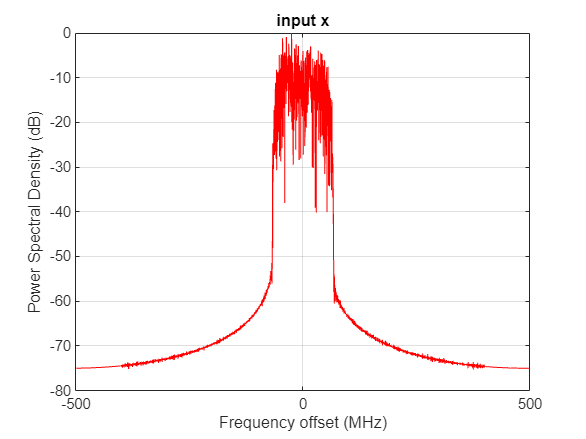

acpr value: -85.36 dB



xadd=xinn.';  %%% xadd is column, xin is row vector
yadd=youtn.';

spec_plot(xinn,10/Fs,1000,'input x');

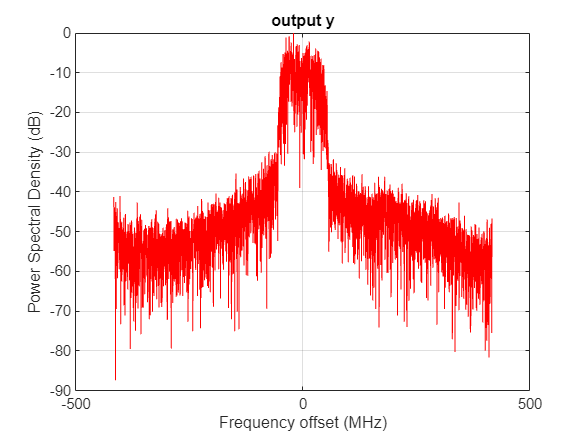

acpr value: -33.18 dB


spec_plot(youtn,12/Fs,1001,'output y');

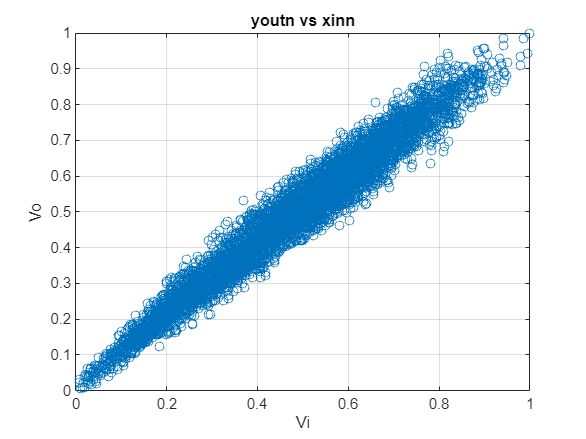


figure(1)
plot(abs(xadd),abs(yadd),'o'); grid on; title('youtn vs xinn')
grid on
xlabel('Vi');
ylabel('Vo');

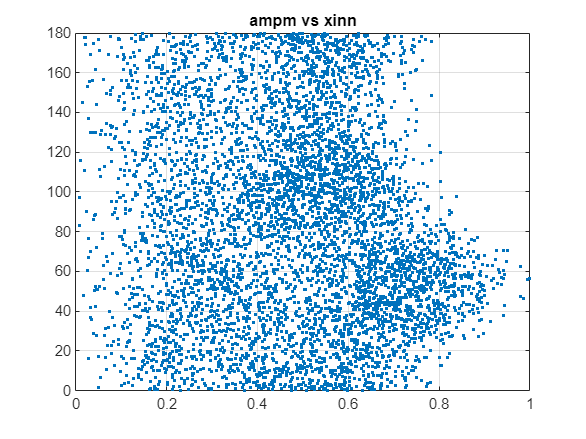


%plot(abs(xadd),unwrap(angle(yadd./xadd)),'.')
ampm1=angle(yadd./conj(xadd))*180/pi;
ampm1=mod(ampm1,180);
index1=find(ampm1>180);
figure(11)
plot(abs(xadd),ampm1,'.'); grid on; title('ampm vs xinn')

## choose samples in middle of record so it will be possible to do time shifts easily

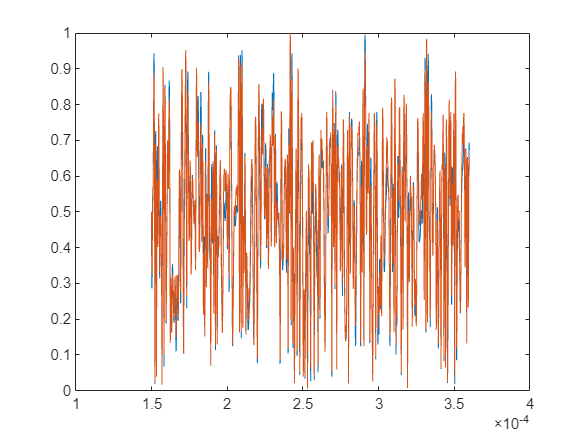

Npmin=1500;
Npmax=3600;
figure(12)
plot(tsig(Npmin:Npmax),abs(xadd(Npmin:Npmax)),tsig(Npmin:Npmax),abs(yadd(Npmin:Npmax)))

% figure(13)
% plot(tsig(Npmin:Npmax),real(xadd(Npmin:Npmax)),tsig(Npmin:Npmax),-real(yadd(Npmin:Npmax)))
% figure(14)
% plot(tsig(Npmin:Npmax),imag(xadd(Npmin:Npmax)),tsig(Npmin:Npmax),imag(yadd(Npmin:Npmax)))

## determine average phase difference to compare phases

dphase=mean(unwrap(angle(xadd))+unwrap(angle(yadd))) dphase = mean((angle(yadd))-(angle(xadd)));

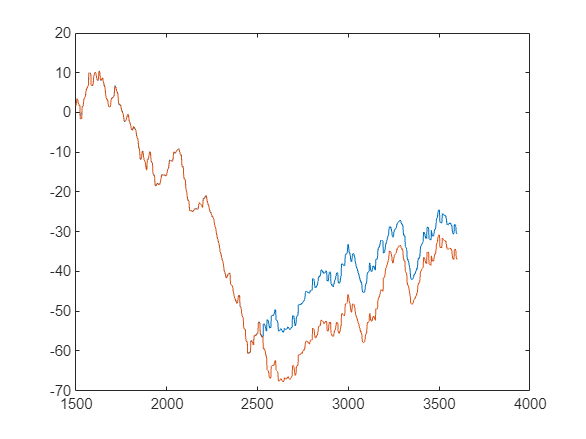

dphase1 = angle(mean(exp(i*(angle(yadd) - angle(xadd)))));
yadd1 = yadd .* exp(i *dphase1);

figure(96)
plot(Npmin:Npmax,unwrap(angle(xadd(Npmin:Npmax))),Npmin:Npmax,unwrap(angle(yadd(Npmin:Npmax))))

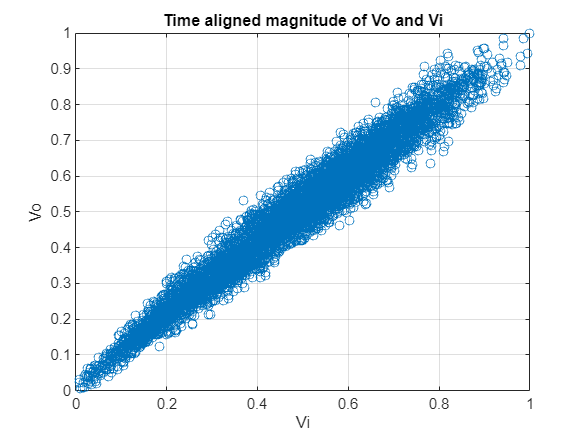



figure(2)
plot(abs(xadd),abs(yadd1),'o'); grid on; title('Time aligned magnitude of Vo and Vi')
grid on
xlabel('Vi');
ylabel('Vo');


%nrmsesq=sum(abs(yadd1-xadd).^2)/sum(abs(xadd).^2)
nrmsesq=mean(abs(yadd1 - xadd).^2)

nrmsesq = 0.0027

nrmse=sqrt(nrmsesq)

nrmse = 0.0520

Power spectral density

w=hann(Nmax-Nmin);
Pxx=pwelch(yadd,w,[]);
Pxx=fftshift(Pxx);
% f = Fs*((0:length(Pxx)-1)/length(Pxx) - 0.5);
f=linspace(-0.5,0.5,length(Pxx))*(Fs/10);
BW_channel = 130e6;
Adj_offset = 150e6;

% Channels index
ind_channel= f>-1*BW_channel/2 & f<BW_channel/2;
% ind_upper= f>70e6 & f<200e6;
% ind_lower= f>-200e6 & f<-70e6;

ind_upper= f>Adj_offset-BW_channel/2 & f<Adj_offset+BW_channel/2;
ind_lower= f>-Adj_offset-BW_channel/2 & f<-Adj_offset+BW_channel/2;

% Riemann integral
int_channel=sum(Pxx(ind_channel))/sum(ind_channel);
int_upper=sum(Pxx(ind_upper))/sum(ind_upper);
int_lower=sum(Pxx(ind_lower))/sum(ind_lower);

acpr_l1=int_lower/int_channel;
acpr_u1=int_upper/int_channel;

acp1_l = 10*log10(acpr_l1);
acp1_u = 10*log10(acpr_u1);
acpr=10*log10(max(acpr_l1,acpr_u1))

acpr = -32.3366

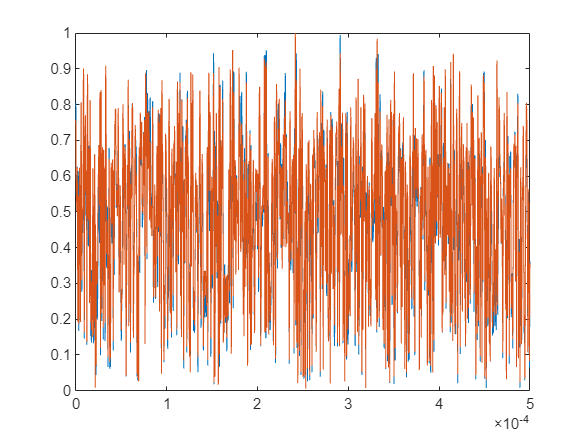

plot(time(1:5000),abs(xin(1:5000)),time(1:5000),abs(yout(1:5000)))